## Field Desorption Map

**Creating field desorption maps and field desorption map movie**

The field desorption map can be rather informative and comprise information such as the location of grain boundaries, differing phases, pole figures, and others. For the construction of a field desorption map, the x- and y-coordinates of the hit events on the detector are needed. Therefore, instead of the mostly used *posIn* variable, for example an *.epos file needs to be loaded. This is also possible with the function *posToTable*.

epos = posToTable; % loading of an *.epos file
 

Then the detector plane is divided into bins. As distance variables the x- and y-coordinates of the detector are used

dist = [epos.detx, epos.dety]; % determination of the distance variables to be binned
bin = [0.1 0.1]; % bin width in x and y direction, in nm
mode = 'distance'; % only possible mode in 2D and 3D
[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode); % creates bin centers and bin edges of the voxels
 

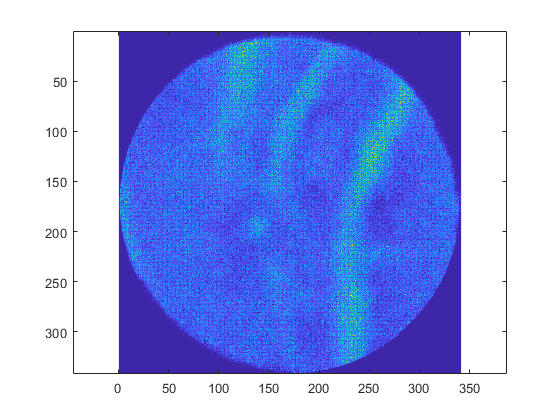

from = 1;
to = 500000;
FDM = hist3([epos.detx(from:to), epos.dety(from:to)],binCenters);
imageFDM = imagesc(FDM); axis equal; 